k=5;

hourRate=table2array(readtable("Import.xlsx"));

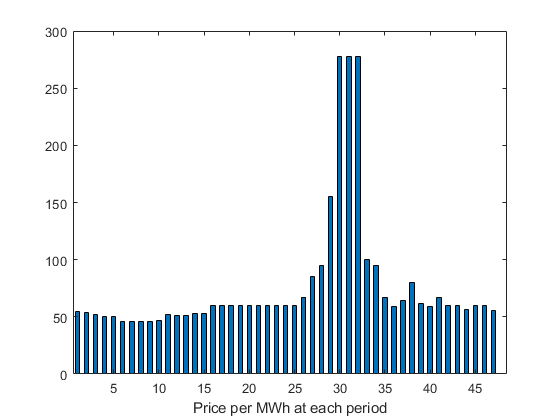

%load dispatchPrice; 
bar(hourRate,.5)
xlim([.5,48.5])
xlabel('Price per MWh at each period')


fuelPrice = 3;
totalfuel = 3.95e4;
nPeriods = length(poolPrice); % 24 periods
nGens = 2; 
gen = [61,83.75,106.5,129.25,152;50,75,100,125,150]; % Generator 1 low = 61 MW, high = 152 MW
fuel = [427,520.75,616.5,711.25,806;325,435,545,655,765];
demand = randi([75,300],48,1);
disp(demand);

   274
   237
    79
   227
   174
   173
   101
   259
   148
   130
   152
   159
   198
   201
   164
   164
   191
   223
   289
   238
   165
   263
   105
    88
    94
   112
   148
   143
    77
   197
    96
   108
   217
   269
   295
   204
   300
   200
   191
   149
   172
   186
    91
   275
    89
   173
   261
   164



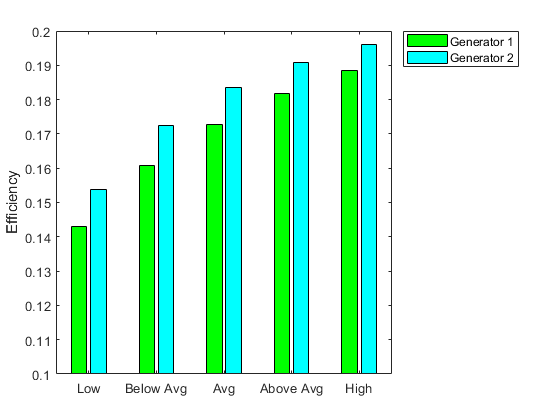

startCost = 1e4; % Cost to start a generator after it has been off\

efficiency = gen./fuel; % Calculate electricity per unit fuel use
rr = efficiency'; % for plotting
h = bar(rr);
h(1).FaceColor = 'g';
h(2).FaceColor = 'c';
legend(h,'Generator 1','Generator 2','Location','NorthEastOutside');
ax = gca;
ax.XTick = [1,2,3,4,5];
ax.XTickLabel = {'Low','Below Avg','Avg','Above Avg','High'};
ylim([.1,.2]);
ylabel('Efficiency');


y = optimvar('y',nPeriods,nGens,{'Low','Below Avg','Avg','Above Avg','High'},'Type','integer','LowerBound',0,'UpperBound',1);
z = optimvar('z',nPeriods,nGens,'Type','integer','LowerBound',0,'UpperBound',1);
show(y);showbounds(y);


(:, :, 'Low') =

    [ y(1, 1, 'Low')     y(1, 2, 'Low')  ]
    [ y(2, 1, 'Low')     y(2, 2, 'Low')  ]
    [ y(3, 1, 'Low')     y(3, 2, 'Low')  ]
    [ y(4, 1, 'Low')     y(4, 2, 'Low')  ]
    [ y(5, 1, 'Low')     y(5, 2, 'Low')  ]
    [ y(6, 1, 'Low')     y(6, 2, 'Low')  ]
    [ y(7, 1, 'Low')     y(7, 2, 'Low')  ]
    [ y(8, 1, 'Low')     y(8, 2, 'Low')  ]
    [ y(9, 1, 'Low')     y(9, 2, 'Low')  ]
    [ y(10, 1, 'Low')    y(10, 2, 'Low') ]
    [ y(11, 1, 'Low')    y(11, 2, 'Low') ]
    [ y(12, 1, 'Low')    y(12, 2, 'Low') ]
    [ y(13, 1, 'Low')    y(13, 2, 'Low') ]
    [ y(14, 1, 'Low')    y(14, 2, 'Low') ]
    [ y(15, 1, 'Low')    y(15, 2, 'Low') ]
    [ y(16, 1, 'Low')    y(16, 2, 'Low') ]
    [ y(17, 1, 'Low')    y(17, 2, 'Low') ]
    [ y(18, 1, 'Low')    y(18, 2, 'Low') ]
    [ y(19, 1, 'Low')    y(19, 2, 'Low') ]
    [ y(20, 1, 'Low')    y(20, 2, 'Low') ]
    [ y(21, 1, 'Low')    y(21, 2, 'Low') ]
    [ y(22, 1, 'Low')    y(22, 2, 'Low') ]
    [ y(23, 1, 'Low')    y(23, 2, 'L

powercons = y(:,:,'Low') +y(:,:,'Below Avg') +y(:,:,'Avg') +y(:,:,'Above Avg') + y(:,:,'High') <= 1;
show(powercons);


(1, 1)

  y(1, 1, 'Low') + y(1, 1, 'Below Avg') + y(1, 1, 'Avg') + y(1, 1, 'Above Avg') + y(1, 1, 'High') <= 1

(2, 1)

  y(2, 1, 'Low') + y(2, 1, 'Below Avg') + y(2, 1, 'Avg') + y(2, 1, 'Above Avg') + y(2, 1, 'High') <= 1

(3, 1)

  y(3, 1, 'Low') + y(3, 1, 'Below Avg') + y(3, 1, 'Avg') + y(3, 1, 'Above Avg') + y(3, 1, 'High') <= 1

(4, 1)

  y(4, 1, 'Low') + y(4, 1, 'Below Avg') + y(4, 1, 'Avg') + y(4, 1, 'Above Avg') + y(4, 1, 'High') <= 1

(5, 1)

  y(5, 1, 'Low') + y(5, 1, 'Below Avg') + y(5, 1, 'Avg') + y(5, 1, 'Above Avg') + y(5, 1, 'High') <= 1

(6, 1)

  y(6, 1, 'Low') + y(6, 1, 'Below Avg') + y(6, 1, 'Avg') + y(6, 1, 'Above Avg') + y(6, 1, 'High') <= 1

(7, 1)

  y(7, 1, 'Low') + y(7, 1, 'Below Avg') + y(7, 1, 'Avg') + y(7, 1, 'Above Avg') + y(7, 1, 'High') <= 1

(8, 1)

  y(8, 1, 'Low') + y(8, 1, 'Below Avg') + y(8, 1, 'Avg') + y(8, 1, 'Above Avg') + y(8, 1, 'High') <= 1

(9, 1)

  y(9, 1, 'Low') + y(9, 1, 'Below Avg') + y(9, 1, 'Avg') + y(9, 1, 'Above Avg') + y(9, 1, 'High


yFuel = zeros(nPeriods,nGens,k);
for c = 1:nGens
    for r = 1:k
        yFuel(:,c,r) = fuel(c,r);
    end
end
fuelUsed = sum(sum(sum(y.*yFuel)));
fuelcons = fuelUsed <= totalfuel;

w = optimexpr(nPeriods,nGens); % Allocate w
idx = 1:(nPeriods-1);
w(idx,:) = y(idx+1,:,'Low') - y(idx,:,'Low') + y(idx+1,:,'Below Avg') - y(idx,:,'Below Avg') +y(idx+1,:,'Avg') - y(idx,:,'Avg') +y(idx+1,:,'Above Avg') - y(idx,:,'Above Avg') +y(idx+1,:,'High') - y(idx,:,'High');
w(nPeriods,:) = y(1,:,'Low') - y(nPeriods,:,'Low') +y(1,:,'Below Avg') - y(nPeriods,:,'Below Avg') +y(1,:,'Avg') - y(nPeriods,:,'Avg') +y(1,:,'Above Avg') - y(nPeriods,:,'Above Avg') + y(1,:,'High') - y(nPeriods,:,'High');
switchcons = w - z <= 0;

generatorlevel  = zeros(size(yFuel));
for c = 1:nGens
    for r = 1:k
        generatorlevel(:,c,r) = gen(c,r);
    end
end


revenue = optimexpr(size(y));
for ii = 1:nPeriods
    revenue(ii,:,:) = poolPrice(ii)*y(ii,:,:).*generatorlevel(ii,:,:);
end

fuelCost = fuelUsed*fuelPrice;
startingCost = z*startCost;
profit = sum(sum(sum(revenue))) - fuelCost - sum(sum(startingCost));

demandcons= y(:,1,1)*gen(1,1)+y(:,1,2)*gen(1,2)+y(:,1,3)*gen(1,3)+y(:,1,4)*gen(1,4)+y(:,1,5)*gen(1,5)+ y(:,2,1)*gen(2,1)+y(:,2,2)*gen(2,2)+y(:,2,3)*gen(2,3)+y(:,2,4)*gen(2,4)+y(:,2,5)*gen(2,5) <= 300;
demandcons1= y(:,1,1)*gen(1,1)+y(:,1,2)*gen(1,2)+y(:,1,3)*gen(1,3)+y(:,1,4)*gen(1,4)+y(:,1,5)*gen(1,5)+ y(:,2,1)*gen(2,1)+y(:,2,2)*gen(2,2)+y(:,2,3)*gen(2,3)+y(:,2,4)*gen(2,4)+y(:,2,5)*gen(2,5) >= 0.7*demand(:,1);

dispatch = optimproblem('ObjectiveSense','maximize');
dispatch.Objective = profit;
dispatch.Constraints.switchcons = switchcons;
dispatch.Constraints.fuelcons = fuelcons;
dispatch.Constraints.powercons = powercons;
dispatch.Constraints.demandcons=demandcons;
dispatch.Constraints.demandcons1=demandcons1;

options = optimoptions('intlinprog','Display','final');

[dispatchsol,fval,exitflag,output] = solve(dispatch,'options',options);


Solving problem using intlinprog.

Optimal solution found.

Intlinprog stopped because the objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon variables are integer within tolerance,
options.IntegerTolerance = 1e-05 (the default value).




subplot(3,1,1)
genOne= dispatchsol.y(:,1,1)*gen(1,1)+dispatchsol.y(:,1,2)*gen(1,2)+dispatchsol.y(:,1,3)*gen(1,3)+dispatchsol.y(:,1,4)*gen(1,4)+dispatchsol.y(:,1,5)*gen(1,5);
bar(genOne,.5,'g')
xlim([.5,48.5])
ylabel('MWh')
title('Generator 1 Optimal Schedule','FontWeight','bold')
subplot(3,1,2)
genTwo=dispatchsol.y(:,2,1)*gen(2,1)+dispatchsol.y(:,2,2)*gen(2,2)+dispatchsol.y(:,2,3)*gen(2,3)+dispatchsol.y(:,2,4)*gen(2,4)+dispatchsol.y(:,2,5)*gen(2,5)

genTwo =    50.0000
   50.0000
   50.0000
  100.0000
  125.0000
  125.0000
   75.0000
   75.0000
  125.0000
  100.0000


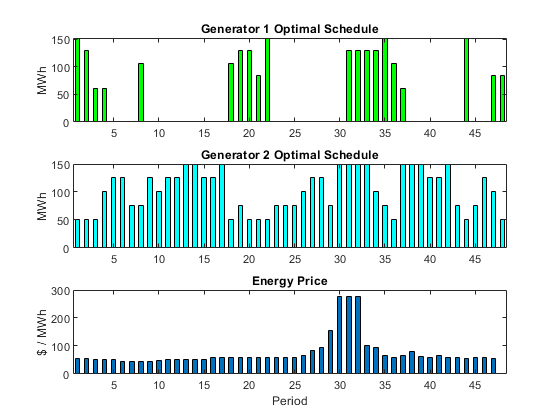

bar(genTwo,.5,'c');
title('Generator 2 Optimal Schedule','FontWeight','bold')
xlim([.5,48.5])
ylabel('MWh')
subplot(3,1,3)
bar(hourRate,.5)
xlim([.5,48.5])
title('Energy Price','FontWeight','bold')
xlabel('Period')
ylabel('$ / MWh')


T= table(genOne,genTwo);
filename="Export.xlsx";
writetable(T,filename,"Sheet",1,"Range","A1")


